# PCL

## Plano_convex Lens profile

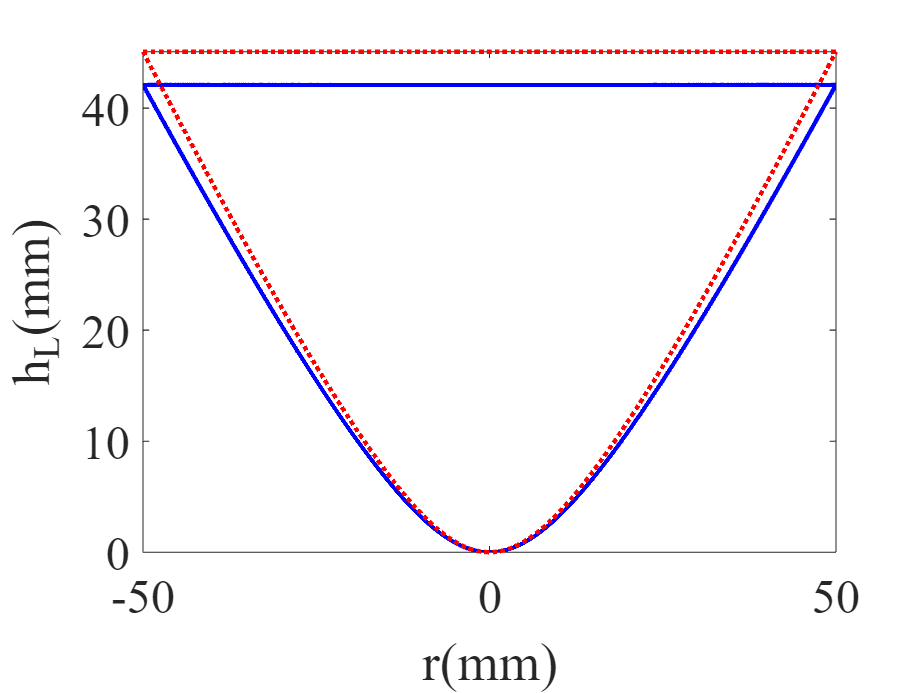

rg=11.9;
rft=400;
d=3000;
Dl=100;
lda0=3;
n=1.45;
w1=1.0*(2)*rg; %mm
w2=2*rft; %mm
alpha_opt=0.79;
%alpha_opt=0.79 is desired
L=52;% CST desired
TT=linspace(0,pi/2,4000000);
H1=(n-1)*L*sin(TT);
H2=(Dl/2)*(n*cos(TT)-1);
H3=abs(H2-H1);
[in1,in2]=min(H3);
theta0=rad2deg(TT(in2));
theta=linspace(0,deg2rad(theta0),2561);
% coll.profile
R=(n-1)*L./(n*cos(theta)-1);
hc=R.*cos(theta)-L;
r=R.*sin(theta);
rf=[-fliplr(r(2:end)),0,r(2:end)];
hcf=[fliplr(hc(2:end)),0,hc(2:end)];
figure
coe1=sqrt(1-exp(-2*(Dl/(2*rg))^2));
coe2=1/((n-1)*d);
coe3=(coe2/coe1)*rft;
F1=@(gm)coe3*sqrt(1-exp(-2*(gm/rg).^2));
F2=@(gm)coe2*(-1)*gm;
F3=@(gm)F1(gm)-F2(gm);% optimized function is considered
hb=zeros(1,length(r));
for i=1:length(r)
    Rp=r(i);
    hb(i)=integral(F3,0,Rp);
end

hbf=[fliplr(hb(2:end)),0,hb(2:end)];
hpcl_opt=alpha_opt*hb+hc;
hpcl=hb+hc;
hb_opt=alpha_opt*hb;
hpclf=[fliplr(hpcl(2:end)),0,hpcl(2:end)];
hpclf_opt=[fliplr(hpcl_opt(2:end)),0,hpcl_opt(2:end)];
plot(rf,hpclf_opt,'b','LineWidth',2)
hold on
constf1=hcf(end)*ones(1,length(rf));
constf2=hbf(end)*ones(1,length(rf));
constf3=hpclf(end)*ones(1,length(rf));
constf3_opt=hpclf_opt(end)*ones(1,length(rf));
plot(rf,constf3_opt,'b','LineWidth',2)
hold on 
plot(rf,hpclf,'r:','LineWidth',2)
hold on
plot(rf,constf3,'r:','LineWidth',2)
ylabel('h_P_C_L(mm)')
xlabel('r(mm)')

set(gca,'fontname','times new roman','fontsize',22)
ylim([0,constf3(1)])
xlim([-50,50])

##  CCL and PCL output beam comparision

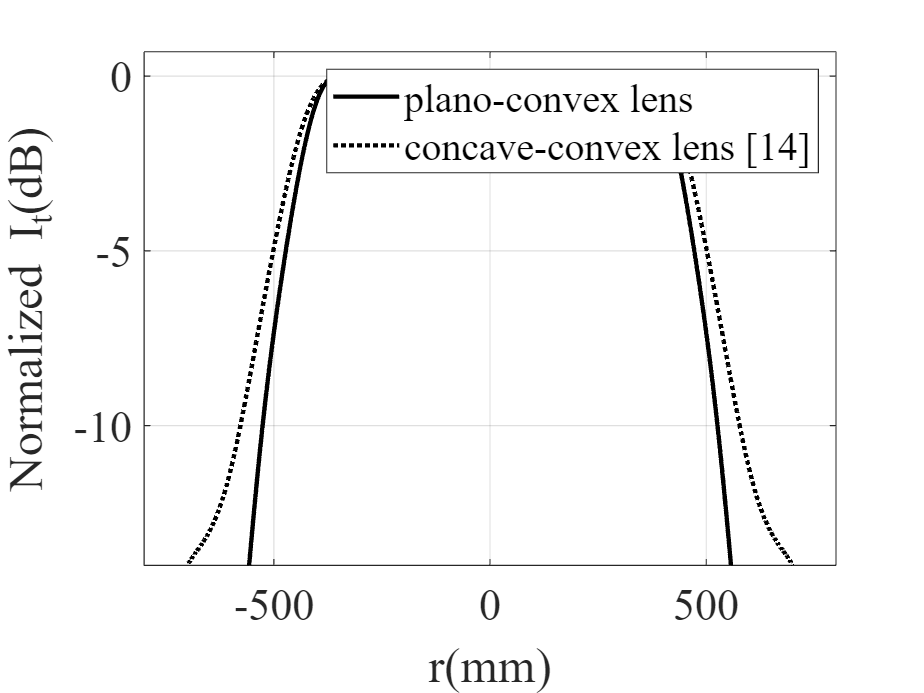

O2=load("PCL_E_field_opt=0.79_CST.txt");
O3=load("CCL_E_field_CST.txt");
ropt=O2(:,1)-900;
rccl=O3(:,1);
Iout_ccl=(O3(:,2)/max(O3(:,2))).^2;
Iout_opt=(O2(:,2)/max(O2(:,2))).^2;

% syms s xp x
% S1=exp(-8*(s^2/w1^2));
% S=int(S1,-Dl/2,xp);
% SD=int(S1,s,-Dl/2,Dl/2);
% phi1=(2*pi)/(lda0*2500)*(w2*((S/SD)-0.5)-xp);
% phi=int(phi1,xp,-Dl/2,x);
% y=rf;
% phi1=subs(phi,x,y);
% phi2=double(phi1);
% phi3=wrapTo2Pi(phi2);
% Iin=exp(-8*(y/w1).^2);
% X=ropt;%linspace(-650,650,length(rf));
% iout=zeros(1,length(X));
% for h=1:length(X)
%     z=X(h);
%     Iout1=sqrt(Iin).*exp(-1i*phi2).*exp(-1i*pi*(1/lda0)*(1/d)*((z-y).^2));
%     iout(h)=trapz(y,Iout1);
% end
% Iout=((abs(iout))/max(abs(iout))).^2;

figure
plot(ropt,10*log10(Iout_opt),'k','LineWidth',2)
hold on
plot(rccl,10*log10(Iout_ccl),'k:','LineWidth',2)
% hold on
% plot(ropt,10*log10(Iout),'k.-','linewidth',2);
xlabel('r(mm)')
ylabel('Normalized I_o_u_t(dB)')
legend('plano-convex lens','concave-convex lens [14]')
grid
xlim([-800,800])
ylim([-14,0.7])
set(gca,'fontname','times new roman','fontsize',20)

## COMSOL vs CST

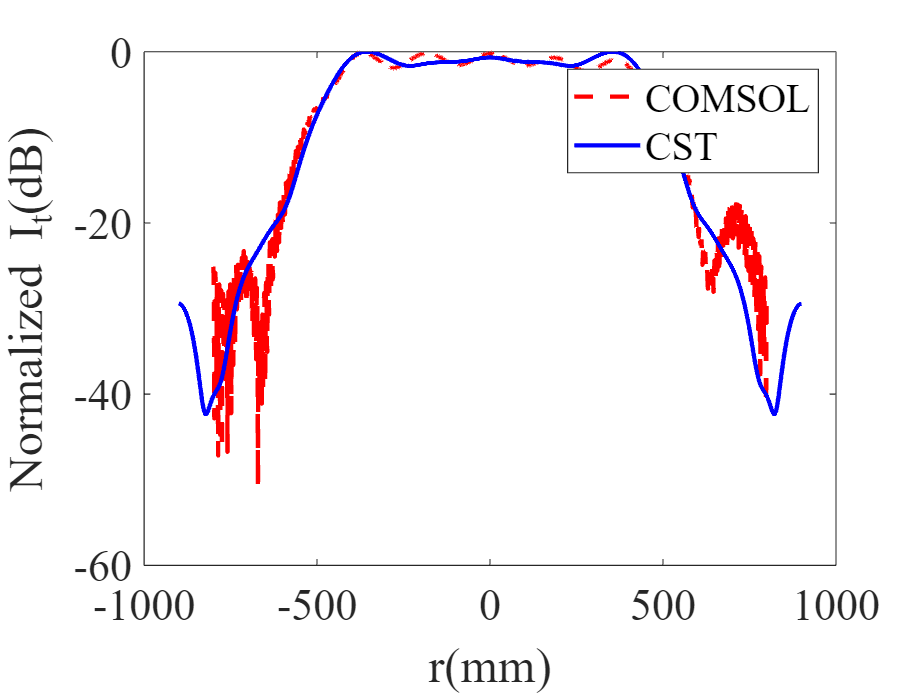

C1=load("PCL_opt0.79_COMSOL - Copy.txt");
rC1=C1(:,1)-800;
Iout_comsol=(C1(:,2)/max(C1(:,2))).^2;
figure
plot(rC1,10*log10(Iout_comsol),'r--','LineWidth',2)
hold on
plot(ropt,10*log10(Iout_opt),'b','LineWidth',2)

xlabel('r(mm)')
ylabel('Normalized I_o_u_t(dB)')
legend('COMSOL','CST')
set(gca,'fontname','times new roman','fontsize',20)

## PCL @ 200GHz Vs PCL @ 100GHz

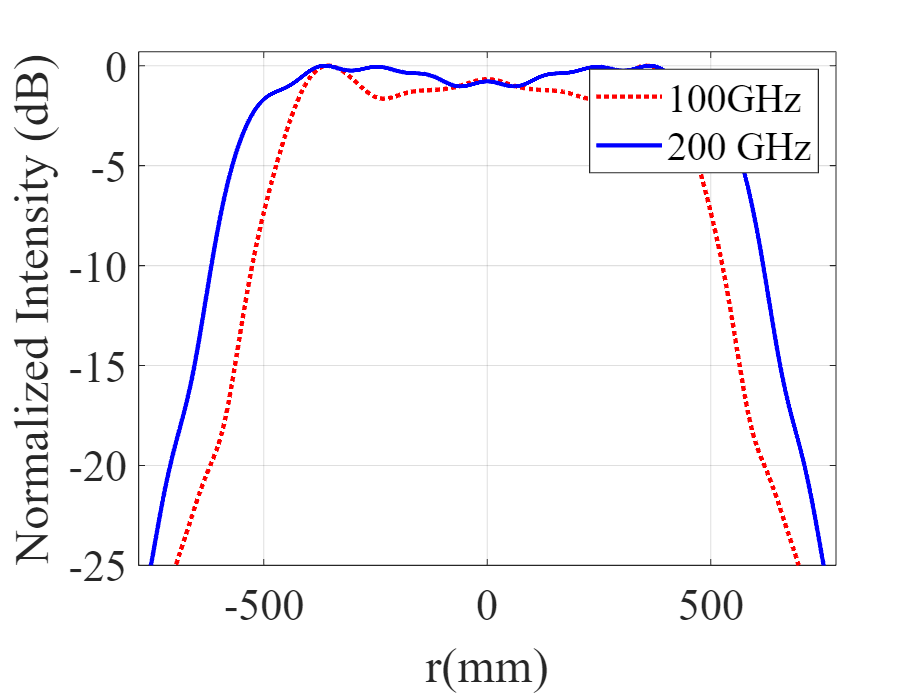

O4=load("PCL_200GHz_E_field_opt=0_CST.txt");
r200G=O4(:,1)-1000;
Iout_200G=(O4(:,2)/max(O4(:,2))).^2;

figure
plot(ropt,10*log10(Iout_opt),'r:','LineWidth',2)
hold on
plot(r200G,10*log10(Iout_200G),'b','LineWidth',2)

% hold on
% plot(ropt,10*log10(Iout),'k.-','linewidth',2);
xlabel('r(mm)')
ylabel('Normalized Intensity (dB)')
legend('100GHz','200 GHz')
grid
xlim([-780,780])
ylim([-25,0.7])
set(gca,'fontname','times new roman','fontsize',20)

## Sensitivity of PCL

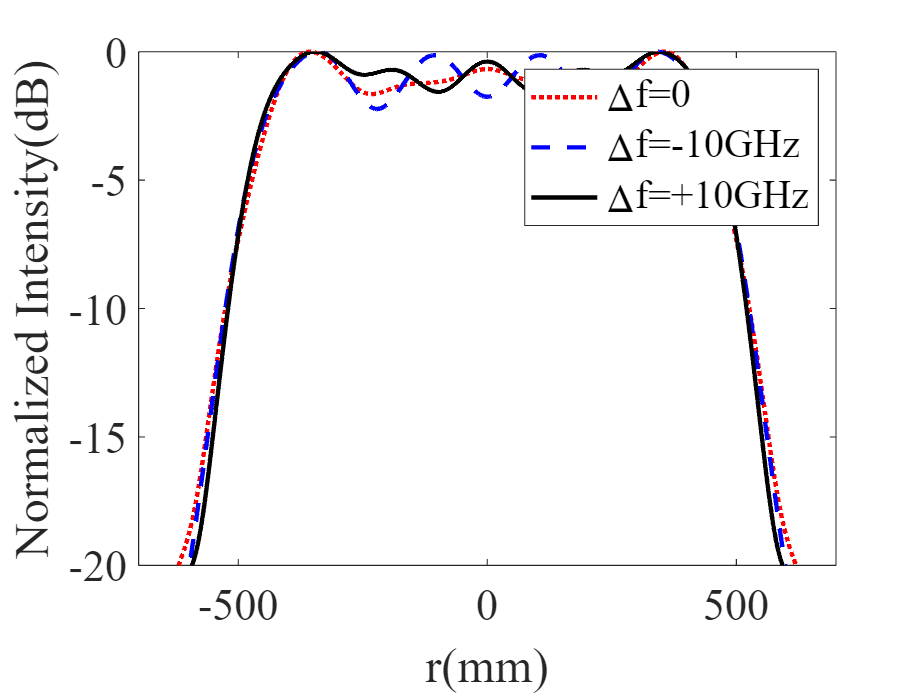

% Frequency
F1=load("PCL_opt0.79_f90.txt");
F2=load("PCL_opt0.79_f110.txt");
xF1=F1(:,1)-900;
xF2=F2(:,1)-900;
IF1=20*log10(F1(:,2)/max(F1(:,2)));
IF2=20*log10(F2(:,2)/max(F2(:,2)));
figure
plot(ropt,10*log10(Iout_opt),'r:','LineWidth',2)
hold on
plot(xF1,IF1,'b--','LineWidth',2)
hold on
plot(xF2,IF2,'k','LineWidth',2)
xlabel('r(mm)')
ylabel('Normalized Intensity(dB)')
legend('\Deltaf=0','\Deltaf=-10GHz','\Deltaf=+10GHz')
set(gca,'fontname','times new roman','fontsize',20)
xlim([-700,700])
ylim([-20,0])

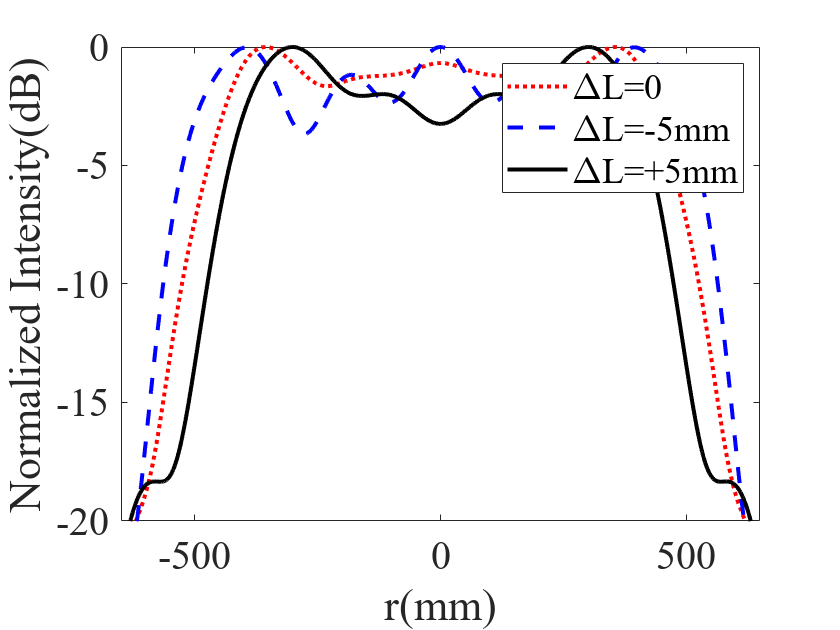


% Distence to Horn
D1=load("PCL_opt0.79_L47.txt");
D2=load("PCL_opt0.79_L57.txt");
xD1=D1(:,1)-900;
xD2=D2(:,1)-900;
ID1=20*log10(D1(:,2)/max(D1(:,2)));
ID2=20*log10(D2(:,2)/max(D2(:,2)));
figure
plot(ropt,10*log10(Iout_opt),'r:','LineWidth',2)
hold on
plot(xD2,ID2,'b--','LineWidth',2)
hold on
plot(xD1,ID1,'k','LineWidth',2)

xlabel('r(mm)')
ylabel('Normalized Intensity(dB)')
legend('\DeltaL=0','\DeltaL=-5mm','\DeltaL=+5mm')
set(gca,'fontname','times new roman','fontsize',20)
xlim([-650,650])
ylim([-20,0])

## Spill-over Eff.

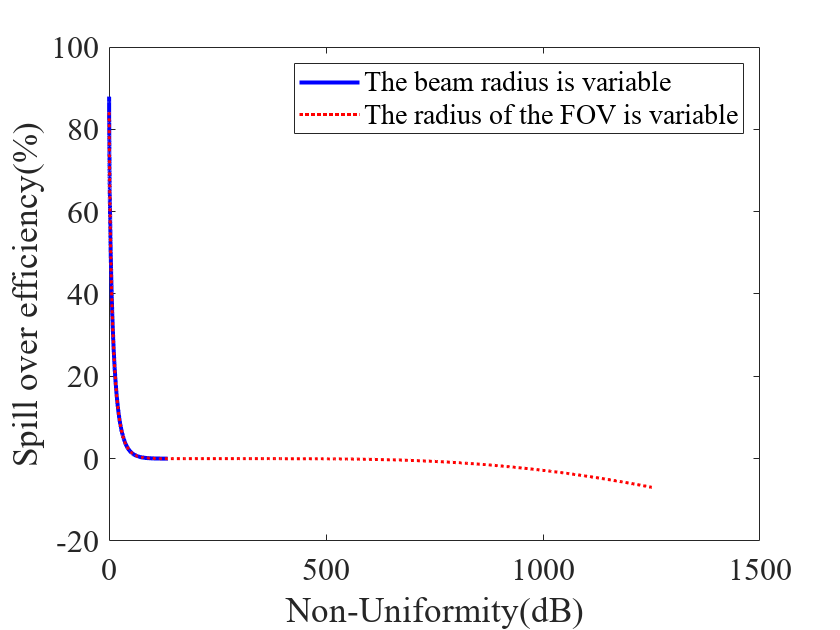

x0=3;
x0min=(1/1.975394)*x0;
x0max=(1/0.075871)*x0;
w0=linspace(x0min,x0max,4000);
nonu=exp(8*(x0./w0).^2);
nonudb=10*log10(nonu);
x=linspace(-0.5*x0,0.5*x0,4000);
y=linspace(-100*x0,100*x0,4000);
spilleff=zeros(1,length(w0));

for i=1:length(w0)
    s1=exp(-8*(x/w0(i)).^2);
    ints1=trapz(x,s1);
    s2=exp(-8*(y/w0(i)).^2);
    ints2=trapz(y,s2);
    spilleff(i)=100-(ints1/ints2)*100;
end

w0p=3;
x0pmin=(0.1)*w0p;
x0pmax=(6)*w0p;
x0p=linspace(x0pmin,x0pmax,4000);
nonup=exp(8*(x0p./w0p).^2);
nonudbp=10*log10(nonup);
spilleffp=zeros(1,length(x0p));

for i=1:length(x0p)
    xp=linspace(-0.5*x0p(i),0.5*x0p(i),4000);
    yp=linspace(-200*x0p(i),200*x0p(i),4000);
    s1p=exp(-8*(xp/w0p).^2);
    ints1p=trapz(xp,s1p);
    s2p=exp(-8*(yp/w0p).^2);
    ints2p=trapz(yp,s2p);
    spilleffp(i)=100-(ints1p/ints2p)*100;
end
figure
plot(nonudb,spilleff,'b','linewidth',2);
hold on
plot(nonudbp,spilleffp,'r:','linewidth',1.5);
xlabel('Non-Uniformity(dB)');
ylabel('Spill over efficiency(%)');
legend('The beam radius is variable','The radius of the FOV is variable')
set(gca,'fontname','times new roman','fontsize',16)

## 3D Output Beam (100GHz)

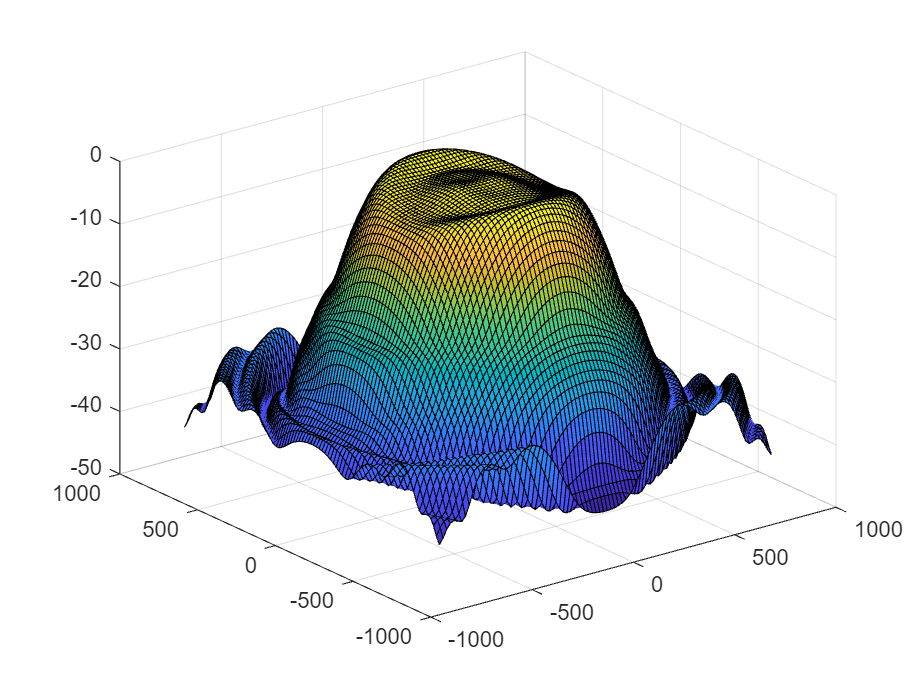

INPUT1 = readtable("3D_output_field_PCL.txt");
DD1=size(INPUT1);
D1=sqrt(DD1(1));
X1 = reshape(INPUT1.Var1,[D1,D1]);
Y1 = reshape(INPUT1.Var2,[D1,D1]);
EXR1=reshape(INPUT1.Var4,[D1,D1]);
EXI1=reshape(INPUT1.Var5,[D1,D1]);
EYR1=reshape(INPUT1.Var6,[D1,D1]);
EYI1=reshape(INPUT1.Var7,[D1,D1]);
EZR1=reshape(INPUT1.Var8,[D1,D1]);
EZI1=reshape(INPUT1.Var9,[D1,D1]);
EXM1=sqrt(EXR1.^2+EXI1.^2);
EYM1=sqrt(EYR1.^2+EYI1.^2);
EZM1=sqrt(EZR1.^2+EZI1.^2);
E3D_abs1 = sqrt(EYM1.^2+EXM1.^2+EZM1.^2);
E3D_abs1=E3D_abs1/max(max(E3D_abs1));
figure
surf(X1,Y1,20*log10(E3D_abs1))

## 3D Output Beam (200GHz)

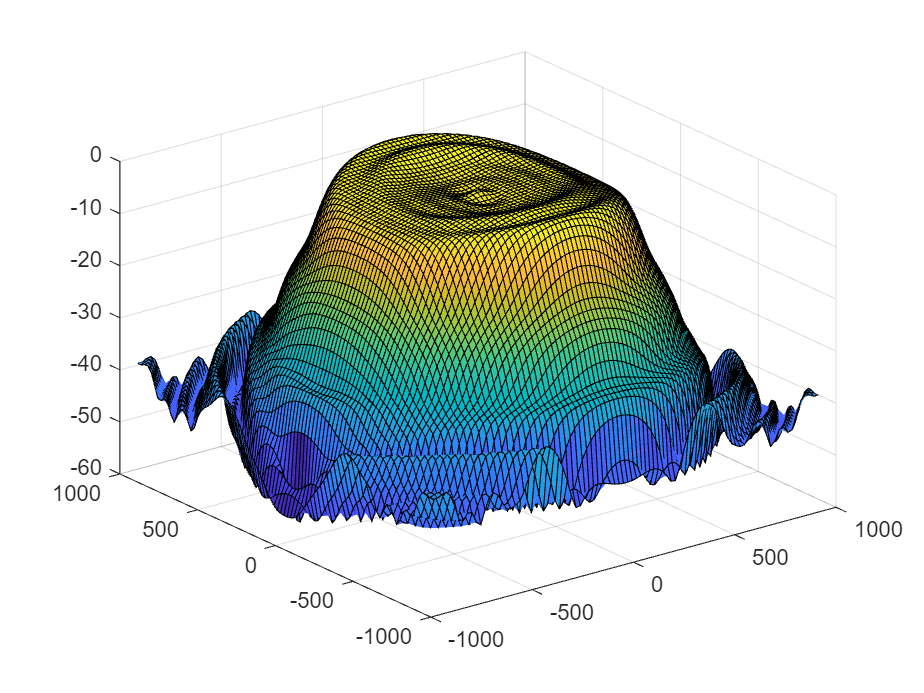

INPUT1 = readtable("3D_output_field_PCL_200GHz.txt");
DD1=size(INPUT1);
D1=sqrt(DD1(1));
X1 = reshape(INPUT1.Var1,[D1,D1]);
Y1 = reshape(INPUT1.Var2,[D1,D1]);
EXR1=reshape(INPUT1.Var4,[D1,D1]);
EXI1=reshape(INPUT1.Var5,[D1,D1]);
EYR1=reshape(INPUT1.Var6,[D1,D1]);
EYI1=reshape(INPUT1.Var7,[D1,D1]);
EZR1=reshape(INPUT1.Var8,[D1,D1]);
EZI1=reshape(INPUT1.Var9,[D1,D1]);
EXM1=sqrt(EXR1.^2+EXI1.^2);
EYM1=sqrt(EYR1.^2+EYI1.^2);
EZM1=sqrt(EZR1.^2+EZI1.^2);
E3D_abs1 = sqrt(EYM1.^2+EXM1.^2+EZM1.^2);
E3D_abs1=E3D_abs1/max(max(E3D_abs1));
figure
surf(X1,Y1,20*log10(E3D_abs1))

## 3D Input Beam of PCL (100GHz)

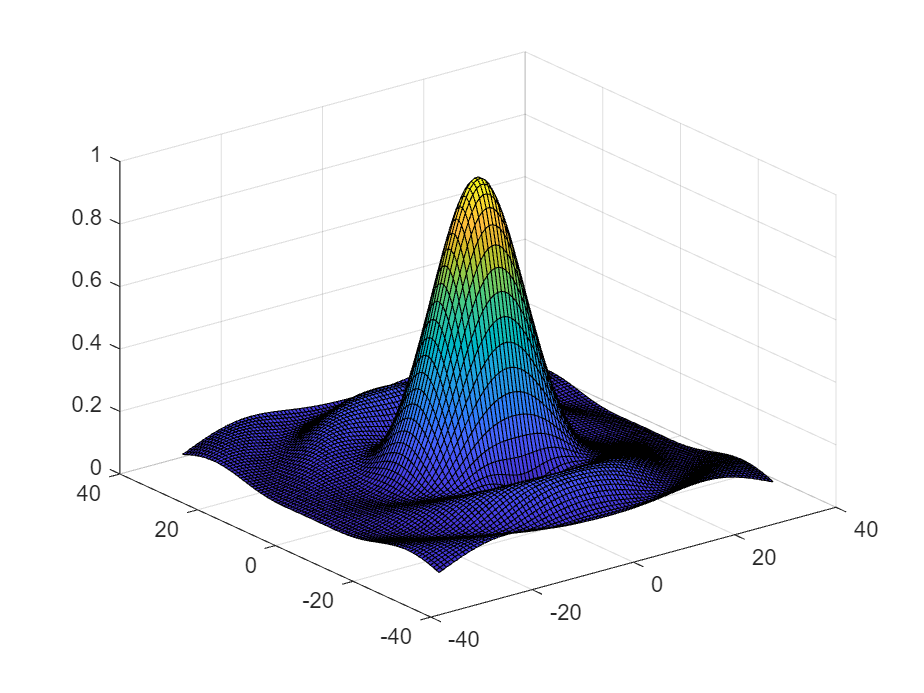

INPUT1 = readtable("3D_input_field_PCL.txt");
DD1=size(INPUT1);
D1=sqrt(DD1(1));
X1 = reshape(INPUT1.Var1,[D1,D1]);
Y1 = reshape(INPUT1.Var2,[D1,D1]);
EXR1=reshape(INPUT1.Var4,[D1,D1]);
EXI1=reshape(INPUT1.Var5,[D1,D1]);
EYR1=reshape(INPUT1.Var6,[D1,D1]);
EYI1=reshape(INPUT1.Var7,[D1,D1]);
EZR1=reshape(INPUT1.Var8,[D1,D1]);
EZI1=reshape(INPUT1.Var9,[D1,D1]);
EXM1=sqrt(EXR1.^2+EXI1.^2);
EYM1=sqrt(EYR1.^2+EYI1.^2);
EZM1=sqrt(EZR1.^2+EZI1.^2);
E3D_abs1 = sqrt(EYM1.^2+EXM1.^2+EZM1.^2);
E3D_abs1=E3D_abs1/max(max(E3D_abs1));
figure
surf(X1,Y1,(E3D_abs1))

## 3D Output beam of Collimator(100GHz)

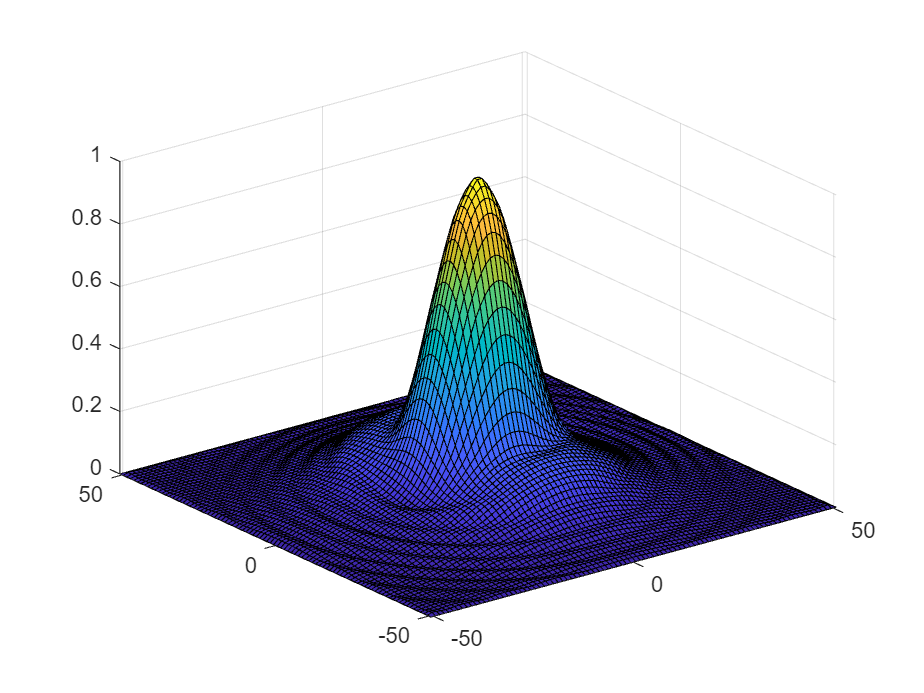


INPUT1 = readtable("3D_output_field_collimator.txt");
DD1=size(INPUT1);
D1=sqrt(DD1(1));
X1 = reshape(INPUT1.Var1,[D1,D1]);
Y1 = reshape(INPUT1.Var2,[D1,D1]);
EXR1=reshape(INPUT1.Var4,[D1,D1]);
EXI1=reshape(INPUT1.Var5,[D1,D1]);
EYR1=reshape(INPUT1.Var6,[D1,D1]);
EYI1=reshape(INPUT1.Var7,[D1,D1]);
EZR1=reshape(INPUT1.Var8,[D1,D1]);
EZI1=reshape(INPUT1.Var9,[D1,D1]);
EXM1=sqrt(EXR1.^2+EXI1.^2);
EYM1=sqrt(EYR1.^2+EYI1.^2);
EZM1=sqrt(EZR1.^2+EZI1.^2);
E3D_abs1 = sqrt(EYM1.^2+EXM1.^2+EZM1.^2);
E3D_abs1=E3D_abs1/max(max(E3D_abs1));
figure
surf(X1,Y1,(E3D_abs1))

## Analytical flattop beam

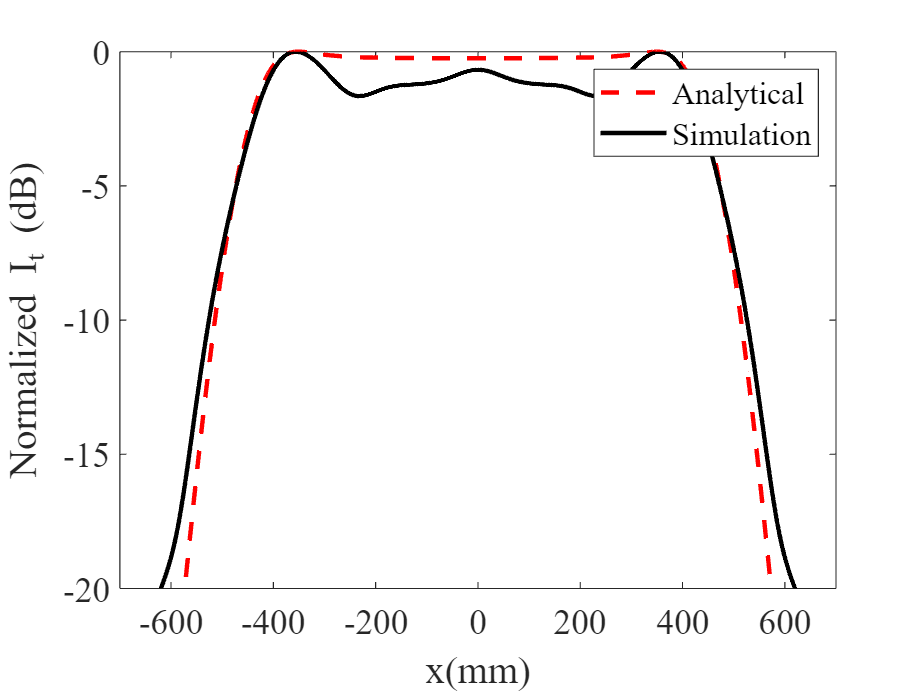

yc=linspace(-100,100,3000);
syms s xp x
S1=exp(-8*(s^2/80^2));
S=int(S1,-200/2,xp);
SD=int(S1,s,-200/2,200/2);
phi1=(2*pi)/(lda0*2000)*(700*((S/SD)-0.5)-xp);
phi2=int(phi1,xp,-200/2,x);
phi3=subs(phi2,x,yc);
phi_u0=double(phi3);


Einn_abs=exp(-4*(yc/80).^2);
[X,Eoutn_A]=SFT(Einn_abs,phi_u0,yc,lda0,2000+710,700);
Iout=abs(Eoutn_A).^2;
figure
plot(X,10*log10(Iout),'r--','linewidth',2);
hold on
plot(ropt,10*log10(Iout_opt),'k','LineWidth',2)
xlabel('x(mm)');
ylabel('Normalized I_o_u_t (dB)');
xlim([-700 700])
ylim([-20 0])
legend('Analytical', 'Simulation')
set(gca,'fontname','times new roman','fontsize',16)

function [X,Eoutn] =SFT(Einn_abs,Einn_phase,x,lambda,do,w2)
X=linspace(-w2,w2,4000);
F1=zeros(1,length(X));
for h=1:length(X)
    z=X(h);
    F0=((Einn_abs)).*exp(-1i*Einn_phase).*exp(-1i*pi*(1/lambda)*(1/do)*((z-x).^2));
    F1(h)=trapz(x,F0);
end
Eoutn=F1/max(abs(F1));
end